***Satellite Rendezvous Demonstration ***

A **satellite rendezvous is when two spacecraft are brought close together** while both are moving at thousands of miles per hour around Earth. Astronauts need to do this when traveling from Earth to the International Space Station. Instead of heading straight for the target, the approaching satellite uses small engine burns to slowly match the target’s speed and altitude. Below is a demonstration of the process.

clear;clc;close all


At the start of a satellite meeting, two spacecraft can be very far apart. **To bring them closer, engineers use a method called a Hohmann transfer. **Instead of flying straight at the target, the chasing spacecraft changes its path with two engine burns. The first burn puts it on a new path that crosses the target’s orbit, letting gravity help with most of the work. The second burn makes sure the spacecraft matches the target’s height and speed at the right time. This way, the spacecraft gets closer using less fuel, making it ready for the final meeting steps.

***Select the Orbit Parameters of the Target Spacecraft here:***

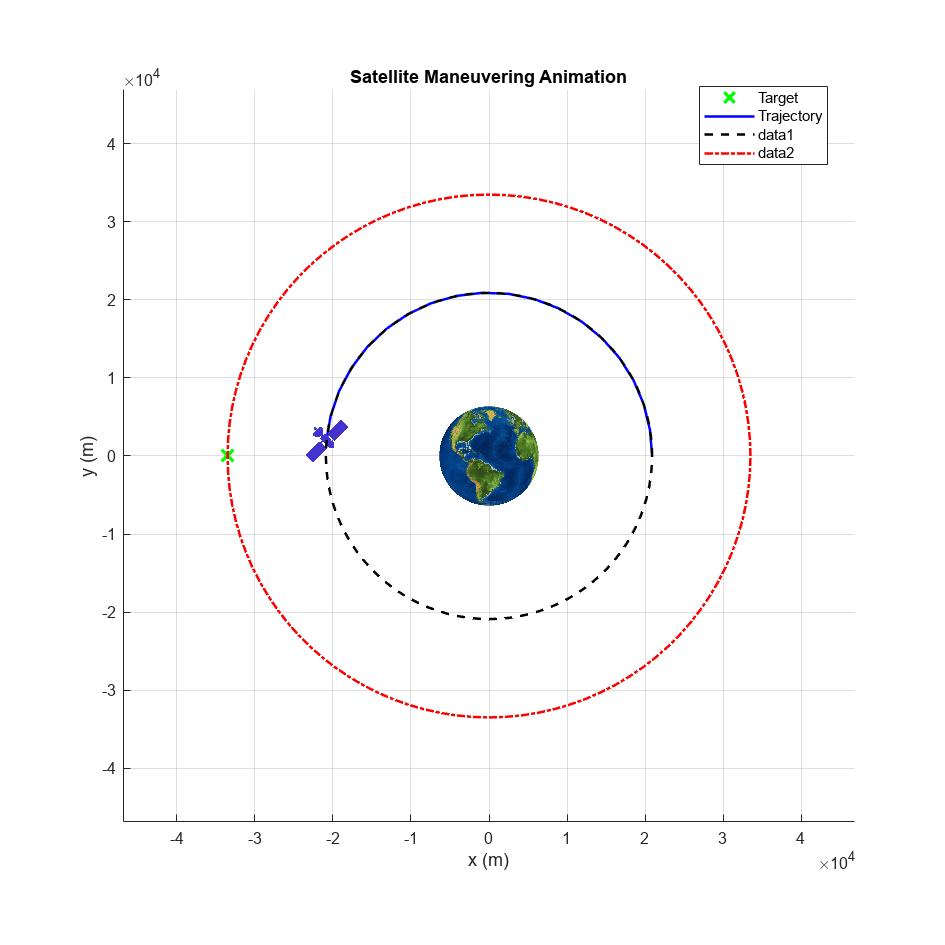

orbitSemiMajorAxis1 =33500; %km
orbitSemiMajorAxis0 =20900; %km

warning('off', 'MATLAB:ode45:IntegrationTolNotMet');
orbitAnimation2D

figure;
set(gcf, 'Color', 'w');
set(gcf, 'Position',  [0, 0, 1080, 1080]*0.7)
hold on; axis equal; grid on;
% Circle parameters
h = 0; % x-coordinate of center
k = 0; % y-coordinate of center

% Implicit equation: (x-h)^(2) + (y-k)^(2) - r^(2) = 0

xlabel('x (m)'); ylabel('y (m)');
title('Satellite Maneuvering Animation');

% Set axis limits with some padding
% x_min = min(x(:,1)); x_max = max(x(:,1));
% y_min = min(x(:,2)); y_max = max(x(:,2));
x_min = -orbitSemiMajorAxis1; x_max = orbitSemiMajorAxis1;
y_min = -orbitSemiMajorAxis1; y_max = orbitSemiMajorAxis1;
dx = x_max - x_min; if dx==0, dx=1; end
dy = y_max - y_min; if dy==0, dy=1; end

% Import and display Earth image
    % Check if image exists
    earthImgFile = 'earth_PNG3.png';
    if exist(earthImgFile, 'file')
        % Read image and alpha channel if available
        [img, ~, alpha] = imread(earthImgFile);
   
        % Constants for Earth
        rEarth = 6378; % km
   
        % Plot image with correct extent
        % XData: [-rEarth, rEarth], YData: [rEarth, -rEarth] (top-down)
        hEarth = image('CData', img, 'XData', [-rEarth rEarth], 'YData', [rEarth -rEarth]);
   
        % Apply transparency if alpha channel exists
        if ~isempty(alpha)
            set(hEarth, 'AlphaData', alpha);
        end
   
        % Ensure axis direction is normal for cartesian plot
        set(gca, 'YDir', 'normal');
    else
        warning('Earth image file "%s" not found.', earthImgFile);
    end
   
    % Plot the target state (origin)
    plot(-rf, 0, 'gx', 'MarkerSize', 10, 'LineWidth', 2, 'DisplayName', 'Target');
   
    % Create animated line for trajectory and marker for satellite
    hTraj = animatedline('LineWidth', 1.5, 'Color', 'b', 'DisplayName', 'Trajectory');

    % Load satellite image
    chaserImgFile = 'chaser2D.png';
    if exist(chaserImgFile, 'file')
        [satImg, ~, satAlpha] = imread(chaserImgFile);
        rSat = 3000; % Visible radius on plot (not to scale)
        % Initial position
        hSat = image('CData', satImg, ...
            'XData', x(1, 1) + [-rSat rSat], ...
            'YData', x(1, 2) + [rSat -rSat]);
        if ~isempty(satAlpha)
            set(hSat, 'AlphaData', satAlpha);
        end
    else
        hSat = plot(x(1, 1), x(1, 2), 'k.', 'MarkerSize', 20, 'DisplayName', 'Satellite');
        warning('Satellite image file "%s" not found. Using default marker.', chaserImgFile);
    end

    x_span = max(x(:,1)) - min(x(:,1));
    y_span = max(x(:,2)) - min(x(:,2));
    avg_span = (x_span + y_span) / 2;
    if avg_span == 0, avg_span = 1; end
    % Thrust vector components for plotting: direction * throttle
    u_vec_plot = u(:, 1:3) .* u(:, 4);
    u_mag = u(:, 4); % Throttle is the magnitude factor (assuming unit direction)
   
    max_u = max(u_mag);
    if max_u == 0, scale_inv = 1; else, scale_inv = (0.15 * avg_span) / max_u; end
    legend('show', 'Location', 'best');
   
   
    % Setup Video Writer
    videoFilename = 'satellite_maneuver.mp4';
    vWriter = VideoWriter(videoFilename, 'MPEG-4');
    vWriter.FrameRate = 20; % Adjust frame rate as needed
    % open(vWriter);
   
    % Loop through time steps to animate
    % Depending on the number of steps in 't', we might want to skip frames to keep video short
    nSteps = length(t);
    frameStep = max(1, floor(nSteps / 200)); % Target approx 300 frames max (~10s at 30fps)
    % viscircles([0 0],[r0],'LineStyle','--','Color',"r");
    % viscircles([0 0],[rf],'LineStyle','--','Color',"k");
    circle(0,0,r0,"k",'--');
    circle(0,0,rf,"r",'-.');

   
    for k = 1:frameStep:nSteps
        xlim([x_min - 0.2*dx, x_max + 0.2*dx]);
        ylim([y_min - 0.2*dy, y_max + 0.2*dy]);
        addpoints(hTraj, x(k, 1), x(k, 2));
        if exist(chaserImgFile, 'file')
            set(hSat, 'XData', x(k, 1) + [-rSat rSat], 'YData', x(k, 2) + [rSat -rSat]);
        else
            set(hSat, 'XData', x(k, 1), 'YData', x(k, 2));
        end
        drawnow;
   
        axis equal;
    end



***Space Debris Capture and Removal***

Spacecraft rendezvous is a key part of capturing space debris. Earth’s orbit is now crowded with satellites and pieces of space junk left over from many years of launches, collisions, and old spacecraft. This debris can move faster than a bullet, so even a small piece can cause serious damage or even destroy working satellites. Active Debris Removal (ADR) refers to technologies and missions that safely capture and remove dangerous objects from orbit to protect future space missions. One promising method for ADR uses tether net systems. An example of this process is shown below:

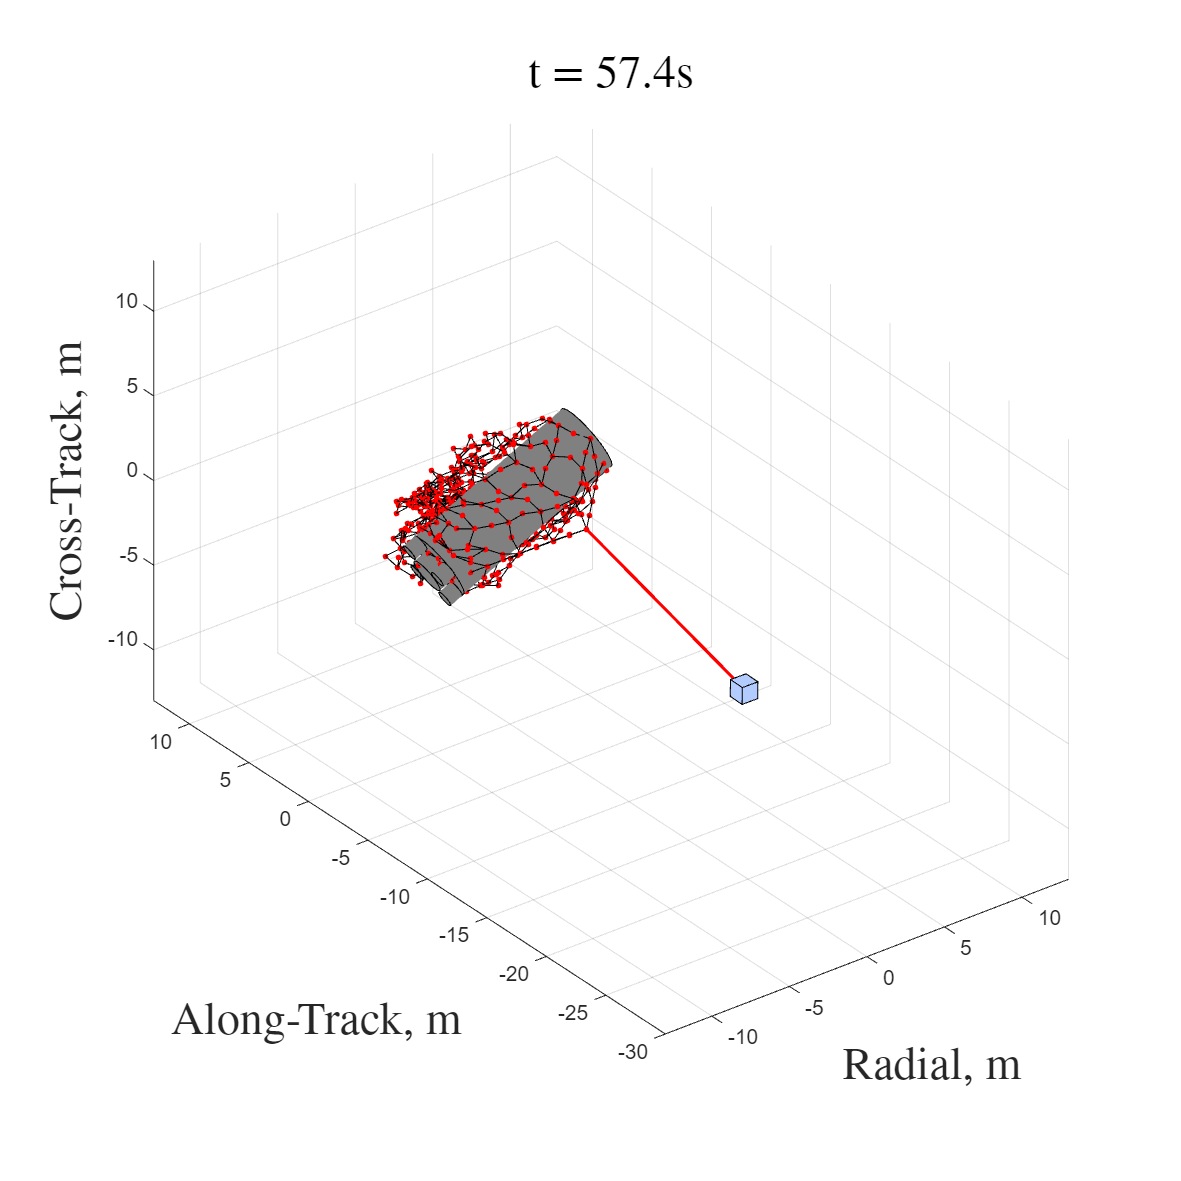


load("dataForNetDemo.mat")
figure
set(gcf, 'Position', [0, 0, 1080, 1080]*0.7)

% for k = 250:5:2450
% for k = 250:10:length(t_plot)
for k = 2:5:900
% for k = saveFrames;
% for k = length(t_plot)
% for k = round( length(t_plot)/ 2 )
% for k = round( length(t_plot)/ 1 )

    q_C = [chaserInfo(k,7:10)]'; 
    rotMat_C_A_I=[ q_C(1)^2+q_C(2)^2-q_C(3)^2-q_C(4)^2  2*(q_C(2)*q_C(3)-q_C(1)*q_C(4))      2*(q_C(2)*q_C(4)+q_C(1)*q_C(3));
                  2*(q_C(2)*q_C(3)+q_C(1)*q_C(4))     q_C(1)^2-q_C(2)^2+q_C(3)^2-q_C(4)^2   2*(q_C(4)*q_C(3)-q_C(1)*q_C(2));
                  2*(q_C(2)*q_C(4)-q_C(3)*q_C(1))     2*(q_C(3)*q_C(4)+q_C(1)*q_C(2))      q_C(1)^2-q_C(2)^2-q_C(3)^2+q_C(4)^2]';

    q_D = [targetInfo(k,7:10)]';
    rotMat_D_A_I=[ q_D(1)^2+q_D(2)^2-q_D(3)^2-q_D(4)^2  2*(q_D(2)*q_D(3)-q_D(1)*q_D(4))      2*(q_D(2)*q_D(4)+q_D(1)*q_D(3));
                  2*(q_D(2)*q_D(3)+q_D(1)*q_D(4))     q_D(1)^2-q_D(2)^2+q_D(3)^2-q_D(4)^2   2*(q_D(4)*q_D(3)-q_D(1)*q_D(2));
                  2*(q_D(2)*q_D(4)-q_D(3)*q_D(1))     2*(q_D(3)*q_D(4)+q_D(1)*q_D(2))      q_D(1)^2-q_D(2)^2-q_D(3)^2+q_D(4)^2]';

    % target centered
    R = targetInfo(k,1:3)'/norm(targetInfo(k,1:3));
    W = cross(R,targetInfo(k,4:6)'/norm(targetInfo(k,4:6)));
    S = cross(W,R);
    RotMat_H_A_I = [R S W]';
    
    targetPosLocal = (RotMat_H_A_I)*targetInfo(k,1:3)';
    chaserPosLocal = (RotMat_H_A_I)*chaserInfo(k,1:3)';
    netPosLocal = (RotMat_H_A_I)*[X_plot(k,:);Y_plot(k,:);Z_plot(k,:)];
    targetInfo(k,1:3)=targetPosLocal';
    chaserInfo(k,1:3)=chaserPosLocal';
    X_plot(k,:) = netPosLocal(1,:)';
    Y_plot(k,:) = netPosLocal(2,:)';
    Z_plot(k,:) = netPosLocal(3,:)';

    % target centered
    X_plot(k,:) = X_plot(k,:) - targetInfo(k,1);
    Y_plot(k,:) = Y_plot(k,:) - targetInfo(k,2);      
    Z_plot(k,:) = Z_plot(k,:) - targetInfo(k,3);
    chaserInfo(k,1) = chaserInfo(k,1) - targetInfo(k,1);
    chaserInfo(k,2) = chaserInfo(k,2) - targetInfo(k,2);
    chaserInfo(k,3) = chaserInfo(k,3) - targetInfo(k,3);
    targetInfo(k,1) = targetInfo(k,1) - targetInfo(k,1);
    targetInfo(k,2) = targetInfo(k,2) - targetInfo(k,2);
    targetInfo(k,3) = targetInfo(k,3) - targetInfo(k,3);

    %net nodes
    scatter3(X_plot(k,:),Y_plot(k,:),Z_plot(k,:),25*M,'r','MarkerFaceColor','r');

    hold on
    %main tether
    plot3([X_plot(k, (n^2+1)/2 ) , chaserInfo(k,1)],[Y_plot(k,(n^2+1)/2), chaserInfo(k,2)],[Z_plot(k,(n^2+1)/2), chaserInfo(k,3)],'r-','LineWidth',1.5);

    % targetPosLocal = targetInfo(:,1:3)';

    Lside = 1;
    % RotMat = eye(3);
    RotMat =RotMat_H_A_I*rotMat_C_A_I';
    drawCube(chaserInfo(k,1), chaserInfo(k,2), chaserInfo(k,3), Lside, RotMat) 

    %net threads
    for i = 1:1:Nlinks
        plot3([X_plot(k,Conn_table(i,1)),X_plot(k,Conn_table(i,2))],[Y_plot(k,Conn_table(i,1)),Y_plot(k,Conn_table(i,2))],[Z_plot(k,Conn_table(i,1)),Z_plot(k,Conn_table(i,2))],'k-');
    end

    %closing threads
    for i = 1:12
        plot3([X_plot(k,closingIndex(i,1)),X_plot(k,closingIndex(i,2))],[Y_plot(k,closingIndex(i,1)),Y_plot(k,closingIndex(i,2))],[Z_plot(k,closingIndex(i,1)),Z_plot(k,closingIndex(i,2))],'b-','LineWidth',1.5);
    end

    %% Drawing targets
    alphaFace = 1;
    drawZenitOrbit2(targetPos, targetInfo, RotMat_H_A_I, rotMat_D_A_I, k, ColorSide, ColorBase, alphaFace);

    %%
    hold off

    axis([targetInfo(k,1)-13,  targetInfo(k,1)+13,  targetInfo(k,2)-30, targetInfo(k,2)+13,  targetInfo(k,3)-13,  targetInfo(k,3)+13]);

    grid on
    str = ['t = ' num2str(t_plot(k)) 's'];
    
    % xlabel('X, m','fontsize', 22,'interpreter','latex')
    % ylabel('Y, m','fontsize', 22,'interpreter','latex')
    % zlabel('Z, m','fontsize', 22,'interpreter','latex')
    
    xlabel('Radial, m','fontsize', 22,'interpreter','latex')
    ylabel('Along-Track, m','fontsize', 22,'interpreter','latex')
    zlabel('Cross-Track, m','fontsize', 22,'interpreter','latex')

    % axis equal
    daspect([1 1 1])
    title(str,'fontsize', 22,'interpreter','latex')

    drawnow;
   
end


function h = circle(x,y,r,Color,lineSt)
hold on
th = 0:pi/50:2*pi;
xunit = r * cos(th) + x;
yunit = r * sin(th) + y;
h = plot(xunit, yunit,"LineStyle",lineSt, "Color",Color,"LineWidth",1.5);
hold off
end